clc; clear;close all;clf;
load direction_sf_tf_data.mat
clear orientation_direction_bayes

cell_num = 72

cell_num = 72

curve_num = 5

curve_num = 5

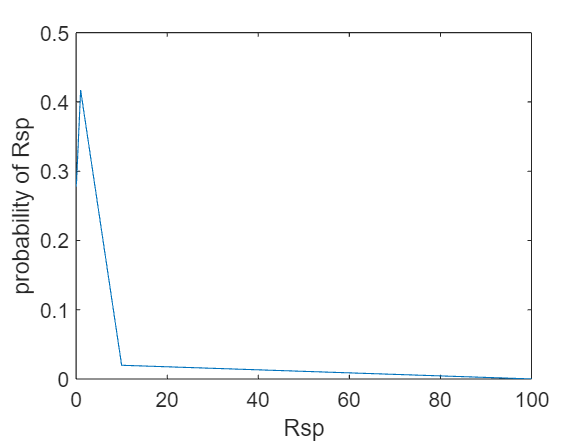

I = struct('Rp',logspace(log10(.5),log10(150),100), ...
    'Op',0:5:359, ...
    'Alpha',linspace(0,1,50), ...
    'Sig',logspace(log10(5),log10(90),10), ...
    'Rsp',logspace(log10(0.01),log10(100),5));
m = [];
v = [];
for cell_num = cell_num
    v = [v,direction_data_s{cell_num}.document_properties.stimulus_tuningcurve.response_stderr];
    m = [m,direction_data_s{cell_num}.document_properties.stimulus_tuningcurve.response_mean];
end
figure(),plot(log10(m),log10(v),'k.'),

mdl = fitlm(log10(m),log10(v)),

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________
    (Intercept)    0.076965     0.01006    7.6507     1.244e-13
    x1              0.48696    0.023814    20.448    4.7596e-66

Number of observations: 448, Error degrees of freedom: 446
Root Mean Squared Error: 0.204
R-squared: 0.484,  Adjusted R-Squared: 0.483
F-statistic vs. constant model: 418, p-value = 4.76e-66

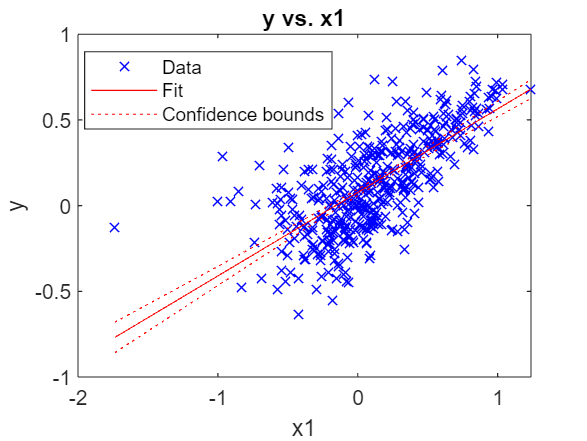

figure(),plot(mdl);

noise_coefficients = mdl.Coefficients{:,1};

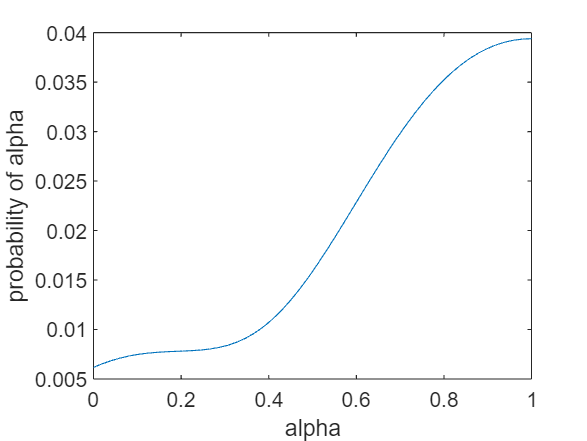

data = extract_direction_data(direction_data_s{cell_num});
figure(),plot_dir_sf_tf(direction_data_s{cell_num});

tic;
[output,Lik] = bayes_grid_function_proportional_noise(I,data(curve_num),noise_coefficients);

rp = 1

rp = 2

rp = 3

rp = 4

rp = 5

rp = 6

rp = 7

rp = 8

rp = 9

rp = 10

rp = 11

rp = 12

rp = 13

rp = 14

rp = 15

rp = 16

rp = 17

rp = 18

rp = 19

rp = 20

rp = 21

rp = 22

rp = 23

rp = 24

rp = 25

rp = 26

rp = 27

rp = 28

rp = 29

rp = 30

rp = 31

rp = 32

rp = 33

rp = 34

rp = 35

rp = 36

rp = 37

rp = 38

rp = 39

rp = 40

rp = 41

rp = 42

rp = 43

rp = 44

rp = 45

rp = 46

rp = 47

rp = 48

rp = 49

rp = 50

rp = 51

rp = 52

rp = 53

rp = 54

rp = 55

rp = 56

rp = 57

rp = 58

rp = 59

rp = 60

rp = 61

rp = 62

rp = 63

rp = 64

rp = 65

rp = 66

rp = 67

rp = 68

rp = 69

rp = 70

rp = 71

rp = 72

rp = 73

rp = 74

rp = 75

rp = 76

rp = 77

rp = 78

rp = 79

rp = 80

rp = 81

rp = 82

rp = 83

rp = 84

rp = 85

rp = 86

rp = 87

rp = 88

rp = 89

rp = 90

rp = 91

rp = 92

rp = 93

rp = 94

rp = 95

rp = 96

rp = 97

rp = 98

rp = 99

rp = 100

toc;

Elapsed time is 1143.916487 seconds.


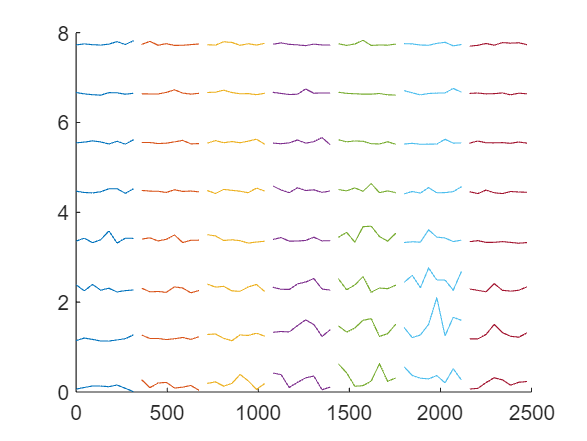

ans = 1

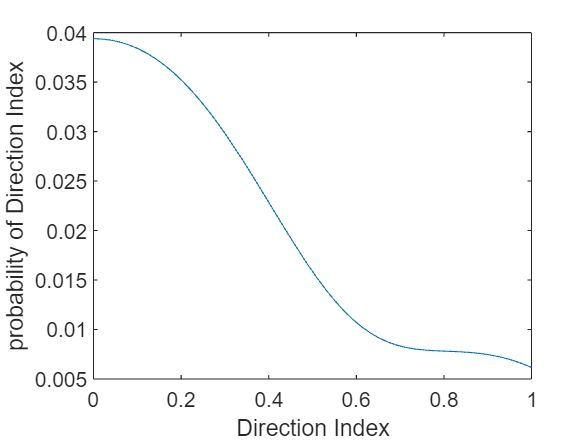

ans = 2

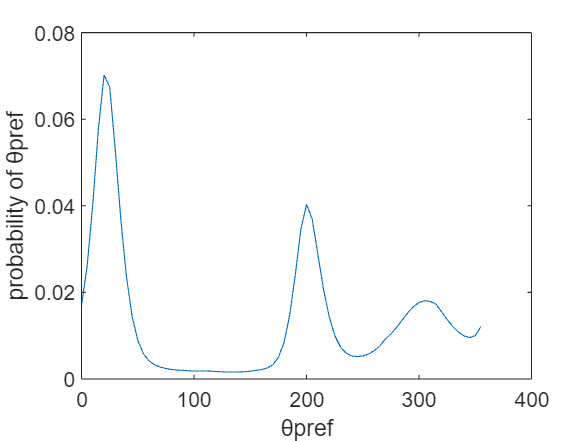

ans = 3

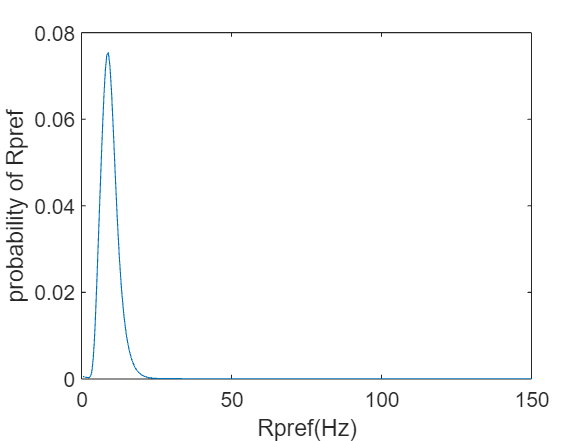

ans = 4

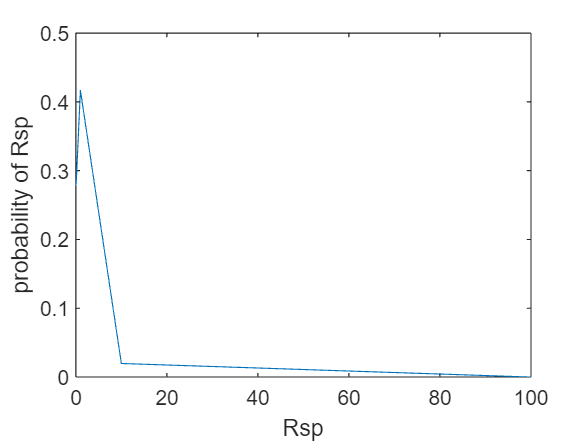

ans = 5

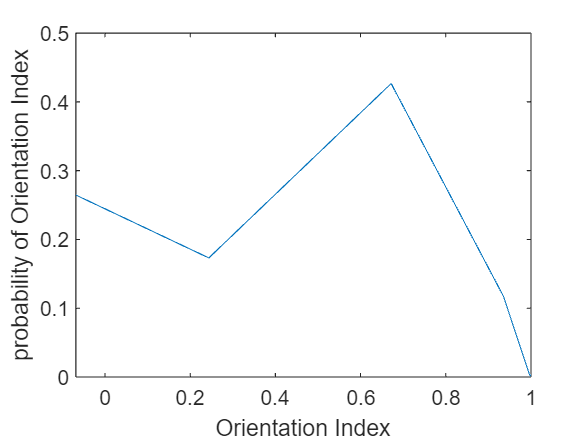

plot_bayes_oridir(output)

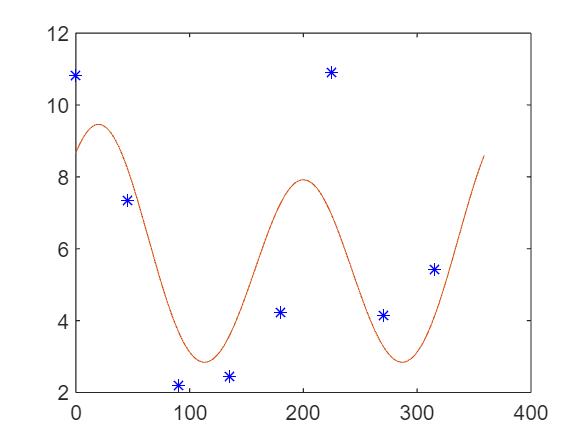

figure(),plot(data(curve_num).angle,data(curve_num).mean_responses,'b*',0:359,output.maximum_likelihood.parameters.tunning_curve)